% This is for task 6
% This creates different LSA models using various parameters and compares
% the results for the preision, recall and F1 of each query to determine
% which is the best model. 

% First I compute the avereage Recall, Precision, and F1 scores over all
% queries for the model used so far. 

 % The next segment of code fills all missing values with 0 so that proper
 % values can be calculated. THis was a major bug that was nicely sovled. 
 [Q1_Table_Euclidean] = fillmissing(Q1_Table_Euclidean,'constant',0);
 [Q2_Table_Euclidean] = fillmissing(Q2_Table_Euclidean,'constant',0);
 [Q3_Table_Euclidean] = fillmissing(Q3_Table_Euclidean,'constant',0);
 [Q4_Table_Euclidean] = fillmissing(Q4_Table_Euclidean,'constant',0);
 [Q5_Table_Euclidean] = fillmissing(Q5_Table_Euclidean,'constant',0);
 [Q6_Table_Euclidean] = fillmissing(Q6_Table_Euclidean,'constant',0);
 [Q7_Table_Euclidean] = fillmissing(Q7_Table_Euclidean,'constant',0);
 [Q8_Table_Euclidean] = fillmissing(Q8_Table_Euclidean,'constant',0);

disp("Average F1 all queries using the initial LSA model")

Average F1 all queries using the initial LSA model


averageF1 = Q1_Table_Euclidean{"F1 Score","Avg"} + Q2_Table_Euclidean{"F1 Score","Avg"} +  Q3_Table_Euclidean{"F1 Score","Avg"}...
            + Q4_Table_Euclidean{"F1 Score","Avg"} + Q5_Table_Euclidean{"F1 Score","Avg"} ...
            + Q6_Table_Cosine{"F1 Score","Avg"} + Q7_Table_Euclidean{"F1 Score","Avg"} + Q8_Table_Euclidean{"F1 Score","Avg"};
            
averageF1 = averageF1/8

averageF1 =    0.155459605819300


disp("Average Precision across all queries using the initial LSA Model")          

Average Precision across all queries using the initial LSA Model


averagePrecision = Q1_Table_Euclidean{"Precision","Avg"} + Q2_Table_Euclidean{"Precision","Avg"} ...
            + Q3_Table_Euclidean{"Precision","Avg"} + Q4_Table_Euclidean{"Precision","Avg"} + Q5_Table_Euclidean{"Precision","Avg"} ... 
            + Q6_Table_Euclidean{"Precision","Avg"} + Q7_Table_Euclidean{"Precision","Avg"} + Q8_Table_Euclidean{"Precision","Avg"};
averagePrecision = averagePrecision/8

averagePrecision =    0.282543540564374



disp("Average Recall Across all queries using the initial LSA model")

Average Recall Across all queries using the initial LSA model


averageRecall = Q1_Table_Euclidean{"Recall","Avg"} + Q2_Table_Euclidean{"Recall","Avg"} ...
           + Q3_Table_Euclidean{"Recall","Avg"} + Q4_Table_Euclidean{"Recall","Avg"} + Q5_Table_Euclidean{"Recall","Avg"} ...
           + Q6_Table_Euclidean{"Recall","Avg"} + Q7_Table_Euclidean{"Recall","Avg"} + Q8_Table_Euclidean{"Recall","Avg"};
averageRecall = averageRecall/8            

averageRecall =    0.101041666666667



% Next I create a tf-idf matrix to determine if using a tf-idf matrix is
 % better than using the normal count matrix available form a bag of words
 % object. 
 % Constructing the tf_idf Matrix using the bag created from the reviews. 
 tf_idf = tfidf(bag_task_4);
 % Constructing the second model
 mdl_2 = fitlsa(tf_idf, num_components);
 % This computes the most similar revies for each query using the second
 % model
 euclidean_table_model_2 = findReviews(queries,mdl_2);
 % The next block of code computes the scores for the queries using the
 % reviews returned from the second model
 [Q1_Table_Model_2] = rankBuilder(euclidean_table_model_2.("Query 1"), query1_relevantIDs);
 [Q2_Table_Model_2] = rankBuilder(euclidean_table_model_2.("Query 2"), query2_relevantIDs);
 [Q3_Table_Model_2] = rankBuilder(euclidean_table_model_2.("Query 3"), query3_relevantIDs);
 [Q4_Table_Model_2] = rankBuilder(euclidean_table_model_2.("Query 4"), query4_relevantIDs);
 [Q5_Table_Model_2] = rankBuilder(euclidean_table_model_2.("Query 5"), query5_relevantIDs);
 [Q6_Table_Model_2] = rankBuilder(euclidean_table_model_2.("Query 6"), query6_relevantIDs);
 [Q7_Table_Model_2] = rankBuilder(euclidean_table_model_2.("Query 7"), query7_relevantIDs);
 [Q8_Table_Model_2] = rankBuilder(euclidean_table_model_2.("Query 8"), query8_relevantIDs);
 
 % The next segment of code fills all missing values with 0 so that proper
 % values can be calculated. THis was a major bug that was nicely sovled. 
 [Q1_Table_Model_2] = fillmissing(Q1_Table_Model_2,'constant',0);
 [Q2_Table_Model_2] = fillmissing(Q2_Table_Model_2,'constant',0);
 [Q3_Table_Model_2] = fillmissing(Q3_Table_Model_2,'constant',0);
 [Q4_Table_Model_2] = fillmissing(Q4_Table_Model_2,'constant',0);
 [Q5_Table_Model_2] = fillmissing(Q5_Table_Model_2,'constant',0);
 [Q6_Table_Model_2] = fillmissing(Q6_Table_Model_2,'constant',0);
 [Q7_Table_Model_2] = fillmissing(Q7_Table_Model_2,'constant',0);
 [Q8_Table_Model_2] = fillmissing(Q8_Table_Model_2,'constant',0);
 
 
 
 % The next block of code computes the average for the scores of each query
 Q1_Table_Model_2.Avg = mean(Q1_Table_Model_2{:,1:end},2);
 Q2_Table_Model_2.Avg = mean(Q2_Table_Model_2{:,1:end},2);
 Q3_Table_Model_2.Avg = mean(Q3_Table_Model_2{:,1:end},2);
 Q4_Table_Model_2.Avg = mean(Q4_Table_Model_2{:,1:end},2);
 Q5_Table_Model_2.Avg = mean(Q5_Table_Model_2{:,1:end},2);
 Q6_Table_Model_2.Avg = mean(Q6_Table_Model_2{:,1:end},2);
 Q8_Table_Model_2.Avg = mean(Q8_Table_Model_2{:,1:end},2);
 Q8_Table_Model_2.Avg = mean(Q8_Table_Model_2{:,1:end},2);
 
 % The next block of code then computes the average of each evaluation
 % metric accross all queries and displays them. Similar to the start of
 % the file
disp("Average F1 over all queries using  model 2")

Average F1 over all queries using  model 2


averageF1_model2 = Q1_Table_Model_2{"F1 Score",end} + Q2_Table_Model_2{"F1 Score",end}  ...
            + Q3_Table_Model_2{"F1 Score",end} + Q4_Table_Model_2{"F1 Score",end} + Q5_Table_Model_2{"F1 Score","Avg"}  ... 
            + Q6_Table_Model_2{"F1 Score",end} + Q7_Table_Model_2{"F1 Score",end} + Q8_Table_Model_2{"F1 Score",end};
            
averageF1_model2= averageF1_model2/8

averageF1_model2 =    0.024319214379569


disp("Average Precision across all queries using model 2")          

Average Precision across all queries using model 2


averagePrecision_model2 = Q1_Table_Model_2{"Precision",end} + Q2_Table_Model_2{"Precision",end} ...
            + Q3_Table_Model_2{"Precision",end} + Q4_Table_Model_2{"Precision","Avg"} + Q5_Table_Model_2{"Precision",end} ...
            + Q6_Table_Model_2{"Precision",end} + Q7_Table_Model_2{"Precision",end} + Q8_Table_Model_2{"Precision",end};
averagePrecision_model2 = averagePrecision_model2/8

averagePrecision_model2 =    0.048814484126984



disp("Average Recall Across all queries using model 2")

Average Recall Across all queries using model 2


averageRecall_model2 = Q1_Table_Model_2{"Recall",end} + Q2_Table_Model_2{"Recall",end} ...
            + Q3_Table_Model_2{"Recall",end} + Q4_Table_Model_2{"Recall",end} + Q5_Table_Model_2{"Recall",end}... 
            + Q6_Table_Model_2{"Recall",end} + Q7_Table_Model_2{"Recall",end} + Q8_Table_Model_2{"Recall",end};
averageRecall_model2 = averageRecall_model2/8  

averageRecall_model2 =    0.017187500000000



% Creating a term-frequency matrix which is normalized using Euclidean
% norm. In our lectures this was called the cosine technique, however, they
% are the same. 
% To do this we need to create a tf-idf matrix, however, we set the idf
% weighting to 1 (unary) and set normailzation to true. This creates a
% normal term count matrix that has been normalized by the length of the
% respective vectors. This is done below using the bag of words object that
% was made form the reviews in task 4

normalized_count_matrix = tfidf(bag_task_4,'IDFWeight',"unary","Normalized",true);

% Creating the third LSA model which is from a normalized term frequency
% matrix and has 200 components. 
model_3 = fitlsa(normalized_count_matrix,num_components)

model_3 =   lsaModel with properties:

              NumComponents: 200
           ComponentWeights: [1×200 double]
             DocumentScores: [200×200 double]
                 WordScores: [918×200 double]
                 Vocabulary: [1×918 string]
    FeatureStrengthExponent: 2



 % This computes the most similar revies for each query using the third
 % model
 euclidean_table_model_3 = findReviews(queries,model_3);
 % The next block of code computes the scores for the queries using the
 % reviews returned from the third model
 [Q1_Table_Model_3] = rankBuilder(euclidean_table_model_3.("Query 1"), query1_relevantIDs);
 [Q2_Table_Model_3] = rankBuilder(euclidean_table_model_3.("Query 2"), query2_relevantIDs);
 [Q3_Table_Model_3] = rankBuilder(euclidean_table_model_3.("Query 3"), query3_relevantIDs);
 [Q4_Table_Model_3] = rankBuilder(euclidean_table_model_3.("Query 4"), query4_relevantIDs);
 [Q5_Table_Model_3] = rankBuilder(euclidean_table_model_3.("Query 5"), query5_relevantIDs);
 [Q6_Table_Model_3] = rankBuilder(euclidean_table_model_3.("Query 6"), query6_relevantIDs);
 [Q7_Table_Model_3] = rankBuilder(euclidean_table_model_3.("Query 7"), query7_relevantIDs);
 [Q8_Table_Model_3] = rankBuilder(euclidean_table_model_3.("Query 8"), query8_relevantIDs);
 
 % The next segment of code fills all missing values with 0 so that proper
 % values can be calculated. THis was a major bug that was nicely sovled. 
 [Q1_Table_Model_3] = fillmissing(Q1_Table_Model_3,'constant',0);
 [Q2_Table_Model_3] = fillmissing(Q2_Table_Model_3,'constant',0);
 [Q3_Table_Model_3] = fillmissing(Q3_Table_Model_3,'constant',0);
 [Q4_Table_Model_3] = fillmissing(Q4_Table_Model_3,'constant',0);
 [Q5_Table_Model_3] = fillmissing(Q5_Table_Model_3,'constant',0);
 [Q6_Table_Model_3] = fillmissing(Q6_Table_Model_3,'constant',0);
 [Q7_Table_Model_3] = fillmissing(Q7_Table_Model_3,'constant',0);
 [Q8_Table_Model_3] = fillmissing(Q8_Table_Model_3,'constant',0);
 
 
 % The next block of code computes the average for the scores of each query
 Q1_Table_Model_3.Avg = mean(Q1_Table_Model_3{:,1:end},2);
 Q2_Table_Model_3.Avg = mean(Q2_Table_Model_3{:,1:end},2);
 Q3_Table_Model_3.Avg = mean(Q3_Table_Model_3{:,1:end},2);
 Q4_Table_Model_3.Avg = mean(Q4_Table_Model_3{:,1:end},2);
 Q5_Table_Model_3.Avg = mean(Q5_Table_Model_3{:,1:end},2);
 Q6_Table_Model_3.Avg = mean(Q6_Table_Model_3{:,1:end},2);
 Q8_Table_Model_3.Avg = mean(Q7_Table_Model_3{:,1:end},2);
 Q8_Table_Model_3.Avg = mean(Q8_Table_Model_3{:,1:end},2);
 
 % The next block of code then computes the average of each evaluation
 % metric accross all queries and displays them. Similar to the start of
 % the file
disp("Average F1 over all queries using  model 3")

Average F1 over all queries using  model 3


averageF1_model3 = Q1_Table_Model_3{"F1 Score",end} + Q2_Table_Model_3{"F1 Score",end}  ...
            + Q3_Table_Model_3{"F1 Score",end} + Q4_Table_Model_3{"F1 Score",end} + Q5_Table_Model_3{"F1 Score","Avg"}  ... 
            + Q6_Table_Model_3{"F1 Score",end} + Q7_Table_Model_3{"F1 Score",end} + Q8_Table_Model_3{"F1 Score",end};
            
averageF1_model3= averageF1_model3/8

averageF1_model3 =      0


disp("Average Precision across all queries using model 3")          

Average Precision across all queries using model 3


averagePrecision_model3 = Q1_Table_Model_3{"Precision",end} + Q2_Table_Model_3{"Precision",end} ...
            + Q3_Table_Model_3{"Precision",end} + Q4_Table_Model_3{"Precision","Avg"} + Q5_Table_Model_3{"Precision",end} ...
            + Q6_Table_Model_3{"Precision",end} + Q7_Table_Model_3{"Precision",end} + Q8_Table_Model_3{"Precision",end};
averagePrecision_model3 = averagePrecision_model3/8

averagePrecision_model3 =      0



disp("Average Recall Across all queries using model 3")

Average Recall Across all queries using model 3


averageRecall_model3 = Q1_Table_Model_3{"Recall",end} + Q2_Table_Model_3{"Recall",end} ...
            + Q3_Table_Model_3{"Recall",end} + Q4_Table_Model_3{"Recall",end} + Q5_Table_Model_3{"Recall",end}... 
            + Q6_Table_Model_3{"Recall",end} + Q7_Table_Model_3{"Recall",end} + Q8_Table_Model_3{"Recall",end};
averageRecall_model3 = averageRecall_model3/8

averageRecall_model3 =      0


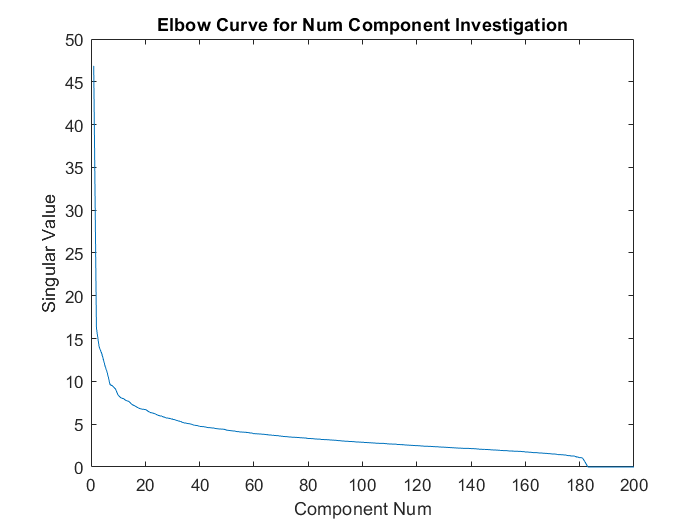



% For model 4 we need to check how many components are to be used. This is
% determined by using an elbow curve of the singular values AKA a Scree
% Plot. 
% This acquires 200 of the singular values as the math requires the numver
% of components to be less than the dictionary size and number of
% documents. 
sigmas = svds(bag_task_4.Counts,200);
figure
plot(sparse(sigmas))
xlabel("Component Num")
ylabel("Singular Value")
title("Elbow Curve for Num Component Investigation")


% Looking at the elbows curve it is seen that the largest "elbows" occur
% at 2 components and 180 components. These two values are compared in
% models 4 and 5

% Creating the fourth model. 
model_4 = fitlsa(bag_task_4,2);

 % This computes the most similar revies for each query using the fourth
 % model
 euclidean_table_model_4 = findReviews(queries,model_4);
 % The next block of code computes the scores for the queries using the
 % reviews returned from the third model
 [Q1_Table_Model_4] = rankBuilder(euclidean_table_model_4.("Query 1"), query1_relevantIDs);
 [Q2_Table_Model_4] = rankBuilder(euclidean_table_model_4.("Query 2"), query2_relevantIDs);
 [Q3_Table_Model_4] = rankBuilder(euclidean_table_model_4.("Query 3"), query3_relevantIDs);
 [Q4_Table_Model_4] = rankBuilder(euclidean_table_model_4.("Query 4"), query4_relevantIDs);
 [Q5_Table_Model_4] = rankBuilder(euclidean_table_model_4.("Query 5"), query5_relevantIDs);
 [Q6_Table_Model_4] = rankBuilder(euclidean_table_model_4.("Query 6"), query6_relevantIDs);
 [Q7_Table_Model_4] = rankBuilder(euclidean_table_model_4.("Query 7"), query7_relevantIDs);
 [Q8_Table_Model_4] = rankBuilder(euclidean_table_model_4.("Query 8"), query8_relevantIDs);
 
  % The next segment of code fills all missing values with 0 so that proper
 % values can be calculated. THis was a major bug that was nicely sovled. 
 [Q1_Table_Model_4] = fillmissing(Q1_Table_Model_4,'constant',0);
 [Q2_Table_Model_4] = fillmissing(Q2_Table_Model_4,'constant',0);
 [Q3_Table_Model_4] = fillmissing(Q3_Table_Model_4,'constant',0);
 [Q4_Table_Model_4] = fillmissing(Q4_Table_Model_4,'constant',0);
 [Q5_Table_Model_4] = fillmissing(Q5_Table_Model_4,'constant',0);
 [Q6_Table_Model_4] = fillmissing(Q6_Table_Model_4,'constant',0);
 [Q7_Table_Model_4] = fillmissing(Q7_Table_Model_4,'constant',0);
 [Q8_Table_Model_4] = fillmissing(Q8_Table_Model_4,'constant',0);
 
 
 % The next block of code computes the average for the scores of each query
 Q1_Table_Model_4.Avg = mean(Q1_Table_Model_4{:,1:end},2);
 Q2_Table_Model_4.Avg = mean(Q2_Table_Model_4{:,1:end},2);
 Q3_Table_Model_4.Avg = mean(Q3_Table_Model_4{:,1:end},2);
 Q4_Table_Model_4.Avg = mean(Q4_Table_Model_4{:,1:end},2);
 Q5_Table_Model_4.Avg = mean(Q5_Table_Model_4{:,1:end},2);
 Q6_Table_Model_4.Avg = mean(Q6_Table_Model_4{:,1:end},2);
 Q8_Table_Model_4.Avg = mean(Q7_Table_Model_4{:,1:end},2);
 Q8_Table_Model_4.Avg = mean(Q8_Table_Model_4{:,1:end},2);
 
 % The next block of code then computes the average of each evaluation
 % metric accross all queries and displays them. Similar to the start of
 % the file
disp("Average F1 over all queries using  model 4")

Average F1 over all queries using  model 4


averageF1_model4 = Q1_Table_Model_4{"F1 Score",end} + Q2_Table_Model_4{"F1 Score",end}  ...
            + Q3_Table_Model_4{"F1 Score",end} + Q4_Table_Model_4{"F1 Score",end} + Q5_Table_Model_4{"F1 Score","Avg"}  ... 
            + Q6_Table_Model_4{"F1 Score",end} + Q7_Table_Model_4{"F1 Score",end} + Q8_Table_Model_4{"F1 Score",end};
            
averageF1_model4= averageF1_model4/8

averageF1_model4 = 0.1646

disp("Average Precision across all queries using model 4")          

Average Precision across all queries using model 4


averagePrecision_model4 = Q1_Table_Model_4{"Precision",end} + Q2_Table_Model_4{"Precision",end} ...
            + Q3_Table_Model_4{"Precision",end} + Q4_Table_Model_4{"Precision","Avg"} + Q5_Table_Model_4{"Precision",end} ...
            + Q6_Table_Model_4{"Precision",end} + Q7_Table_Model_4{"Precision",end} + Q8_Table_Model_4{"Precision",end};
averagePrecision_model4 = averagePrecision_model4/8

averagePrecision_model4 = 0.3048


disp("Average Recall Across all queries using model 4")

Average Recall Across all queries using model 4


averageRecall_model4 = Q1_Table_Model_4{"Recall",end} + Q2_Table_Model_4{"Recall",end} ...
            + Q3_Table_Model_4{"Recall",end} + Q4_Table_Model_4{"Recall",end} + Q5_Table_Model_4{"Recall",end}... 
            + Q6_Table_Model_4{"Recall",end} + Q7_Table_Model_4{"Recall",end} + Q8_Table_Model_4{"Recall",end};
averageRecall_model4 = averageRecall_model4/8

averageRecall_model4 = 0.1212



% Comparing the numbre of components to find the optimal ones. 
model_5 = fitlsa(bag_task_4,180);

 % This computes the most similar revies for each query using the fourth
 % model
 euclidean_table_model_5 = findReviews(queries,model_5);
 % The next block of code computes the scores for the queries using the
 % reviews returned from the third model
 [Q1_Table_Model_5] = rankBuilder(euclidean_table_model_5.("Query 1"), query1_relevantIDs);
 [Q2_Table_Model_5] = rankBuilder(euclidean_table_model_5.("Query 2"), query2_relevantIDs);
 [Q3_Table_Model_5] = rankBuilder(euclidean_table_model_5.("Query 3"), query3_relevantIDs);
 [Q4_Table_Model_5] = rankBuilder(euclidean_table_model_5.("Query 4"), query4_relevantIDs);
 [Q5_Table_Model_5] = rankBuilder(euclidean_table_model_5.("Query 5"), query5_relevantIDs);
 [Q6_Table_Model_5] = rankBuilder(euclidean_table_model_5.("Query 6"), query6_relevantIDs);
 [Q7_Table_Model_5] = rankBuilder(euclidean_table_model_5.("Query 7"), query7_relevantIDs);
 [Q8_Table_Model_5] = rankBuilder(euclidean_table_model_5.("Query 8"), query8_relevantIDs);
 
 
 % The next segment of code fills all missing values with 0 so that proper
 % values can be calculated. THis was a major bug that was nicely sovled. 
 [Q1_Table_Model_5] = fillmissing(Q1_Table_Model_5,'constant',0);
 [Q2_Table_Model_5] = fillmissing(Q2_Table_Model_5,'constant',0);
 [Q3_Table_Model_5] = fillmissing(Q3_Table_Model_5,'constant',0);
 [Q4_Table_Model_5] = fillmissing(Q4_Table_Model_5,'constant',0);
 [Q5_Table_Model_5] = fillmissing(Q5_Table_Model_5,'constant',0);
 [Q6_Table_Model_5] = fillmissing(Q6_Table_Model_5,'constant',0);
 [Q7_Table_Model_5] = fillmissing(Q7_Table_Model_5,'constant',0);
 [Q8_Table_Model_5] = fillmissing(Q8_Table_Model_5,'constant',0);
 
 % The next block of code computes the average for the scores of each query
 Q1_Table_Model_5.Avg = mean(Q1_Table_Model_5{:,1:end},2);
 Q2_Table_Model_5.Avg = mean(Q2_Table_Model_5{:,1:end},2);
 Q3_Table_Model_5.Avg = mean(Q3_Table_Model_5{:,1:end},2);
 Q4_Table_Model_5.Avg = mean(Q4_Table_Model_5{:,1:end},2);
 Q5_Table_Model_5.Avg = mean(Q5_Table_Model_5{:,1:end},2);
 Q6_Table_Model_5.Avg = mean(Q6_Table_Model_5{:,1:end},2);
 Q8_Table_Model_5.Avg = mean(Q7_Table_Model_5{:,1:end},2);
 Q8_Table_Model_5.Avg = mean(Q8_Table_Model_5{:,1:end},2);
 
 % The next block of code then computes the average of each evaluation
 % metric accross all queries and displays them. Similar to the start of
 % the file
disp("Average F1 over all queries using  model 5")

Average F1 over all queries using  model 5


averageF1_model5 = Q1_Table_Model_5{"F1 Score",end} + Q2_Table_Model_5{"F1 Score",end}  ...
            + Q3_Table_Model_5{"F1 Score",end} + Q4_Table_Model_5{"F1 Score",end} + Q5_Table_Model_5{"F1 Score","Avg"}  ... 
            + Q6_Table_Model_5{"F1 Score",end} + Q7_Table_Model_5{"F1 Score",end} + Q8_Table_Model_5{"F1 Score",end};
            
averageF1_model5= averageF1_model5/8

averageF1_model5 = 0.1954

disp("Average Precision across all queries using model 5")          

Average Precision across all queries using model 5


averagePrecision_model5 = Q1_Table_Model_5{"Precision",end} + Q2_Table_Model_5{"Precision",end} ...
            + Q3_Table_Model_5{"Precision",end} + Q4_Table_Model_5{"Precision","Avg"} + Q5_Table_Model_5{"Precision",end} ...
            + Q6_Table_Model_5{"Precision",end} + Q7_Table_Model_5{"Precision",end} + Q8_Table_Model_5{"Precision",end};
averagePrecision_model5 = averagePrecision_model5/8

averagePrecision_model5 = 0.3613


disp("Average Recall Across all queries using model 5")

Average Recall Across all queries using model 5


averageRecall_model5 = Q1_Table_Model_5{"Recall",end} + Q2_Table_Model_5{"Recall",end} ...
            + Q3_Table_Model_5{"Recall",end} + Q4_Table_Model_5{"Recall",end} + Q5_Table_Model_5{"Recall",end}... 
            + Q6_Table_Model_5{"Recall",end} + Q7_Table_Model_5{"Recall",end} + Q8_Table_Model_5{"Recall",end};
averageRecall_model5 = averageRecall_model5/8

averageRecall_model5 = 0.1437



 % This sets the feature strength to be 1. This means the componets are
 % scaled by their singular values using an exponent of 2(4/2 =2). 
model_6 = fitlsa(bag_task_4,2,"FeatureStrengthExponent",4);

 % This computes the most similar revies for each query using the fourth
 % model
 euclidean_table_model_6 = findReviews(queries,model_6);
 % The next block of code computes the scores for the queries using the
 % reviews returned from the third model
 [Q1_Table_Model_6] = rankBuilder(euclidean_table_model_6.("Query 1"), query1_relevantIDs);
 [Q2_Table_Model_6] = rankBuilder(euclidean_table_model_6.("Query 2"), query2_relevantIDs);
 [Q3_Table_Model_6] = rankBuilder(euclidean_table_model_6.("Query 3"), query3_relevantIDs);
 [Q4_Table_Model_6] = rankBuilder(euclidean_table_model_6.("Query 4"), query4_relevantIDs);
 [Q5_Table_Model_6] = rankBuilder(euclidean_table_model_6.("Query 5"), query5_relevantIDs);
 [Q6_Table_Model_6] = rankBuilder(euclidean_table_model_6.("Query 6"), query6_relevantIDs);
 [Q7_Table_Model_6] = rankBuilder(euclidean_table_model_6.("Query 7"), query7_relevantIDs);
 [Q8_Table_Model_6] = rankBuilder(euclidean_table_model_6.("Query 8"), query8_relevantIDs);
 
  % The next segment of code fills all missing values with 0 so that proper
 % values can be calculated. THis was a major bug that was nicely sovled. 
 [Q1_Table_Model_6] = fillmissing(Q1_Table_Model_6,'constant',0);
 [Q2_Table_Model_6] = fillmissing(Q2_Table_Model_6,'constant',0);
 [Q3_Table_Model_6] = fillmissing(Q3_Table_Model_6,'constant',0);
 [Q4_Table_Model_6] = fillmissing(Q4_Table_Model_6,'constant',0);
 [Q5_Table_Model_6] = fillmissing(Q5_Table_Model_6,'constant',0);
 [Q6_Table_Model_6] = fillmissing(Q6_Table_Model_6,'constant',0);
 [Q7_Table_Model_6] = fillmissing(Q7_Table_Model_6,'constant',0);
 [Q8_Table_Model_6] = fillmissing(Q8_Table_Model_6,'constant',0);
 
 
 % The next block of code computes the average for the scores of each query
 Q1_Table_Model_6.Avg = mean(Q1_Table_Model_6{:,1:end},2);
 Q2_Table_Model_6.Avg = mean(Q2_Table_Model_6{:,1:end},2);
 Q3_Table_Model_6.Avg = mean(Q3_Table_Model_6{:,1:end},2);
 Q4_Table_Model_6.Avg = mean(Q4_Table_Model_6{:,1:end},2);
 Q5_Table_Model_6.Avg = mean(Q5_Table_Model_6{:,1:end},2);
 Q6_Table_Model_6.Avg = mean(Q6_Table_Model_6{:,1:end},2);
 Q8_Table_Model_6.Avg = mean(Q7_Table_Model_6{:,1:end},2);
 Q8_Table_Model_6.Avg = mean(Q8_Table_Model_6{:,1:end},2);
 
 % The next block of code then computes the average of each evaluation
 % metric accross all queries and displays them. Similar to the start of
 % the file
disp("Average F1 over all queries using  model 6")

Average F1 over all queries using  model 6


averageF1_model6 = Q1_Table_Model_6{"F1 Score",end} + Q2_Table_Model_6{"F1 Score",end}  ...
            + Q3_Table_Model_6{"F1 Score",end} + Q4_Table_Model_6{"F1 Score",end} + Q5_Table_Model_6{"F1 Score","Avg"}  ... 
            + Q6_Table_Model_6{"F1 Score",end} + Q7_Table_Model_6{"F1 Score",end} + Q8_Table_Model_6{"F1 Score",end};
            
averageF1_model6= averageF1_model6/8

averageF1_model6 =    0.156701865726503


disp("Average Precision across all queries using model 6")          

Average Precision across all queries using model 6


averagePrecision_model6 = Q1_Table_Model_6{"Precision",end} + Q2_Table_Model_6{"Precision",end} ...
            + Q3_Table_Model_6{"Precision",end} + Q4_Table_Model_6{"Precision","Avg"} + Q5_Table_Model_6{"Precision",end} ...
            + Q6_Table_Model_6{"Precision",end} + Q7_Table_Model_6{"Precision",end} + Q8_Table_Model_6{"Precision",end};
averagePrecision_model6 = averagePrecision_model6/8

averagePrecision_model6 =    0.298645833333333



disp("Average Recall Across all queries using model 6")

Average Recall Across all queries using model 6


averageRecall_model6 = Q1_Table_Model_6{"Recall",end} + Q2_Table_Model_6{"Recall",end} ...
            + Q3_Table_Model_6{"Recall",end} + Q4_Table_Model_6{"Recall",end} + Q5_Table_Model_6{"Recall",end}... 
            + Q6_Table_Model_6{"Recall",end} + Q7_Table_Model_6{"Recall",end} + Q8_Table_Model_6{"Recall",end};
averageRecall_model6 = averageRecall_model6/8

averageRecall_model6 =    0.114843750000000


% Model 7. It is the same as model 2 but
% updates the idf weighting scheme. 

% Next I create a tf-idf matrix to determine if using a tf-idf matrix is
 % better than using the normal count matrix available form a bag of words
 % object. 
 % Constructing the tf_idf Matrix using the bag created from the reviews. 
 tf_idf_7 = tfidf(bag_task_4,"IDFWeight","probabilistic");
 % Constructing the second model
 mdl_7 = fitlsa(tf_idf_7, num_components);
 % This computes the most similar revies for each query using the second
 % model
 euclidean_table_model_7 = findReviews(queries,mdl_7);
 % The next block of code computes the scores for the queries using the
 % reviews returned from the second model
 [Q1_Table_Model_7] = rankBuilder(euclidean_table_model_7.("Query 1"), query1_relevantIDs);
 [Q2_Table_Model_7] = rankBuilder(euclidean_table_model_7.("Query 2"), query2_relevantIDs);
 [Q3_Table_Model_7] = rankBuilder(euclidean_table_model_7.("Query 3"), query3_relevantIDs);
 [Q4_Table_Model_7] = rankBuilder(euclidean_table_model_7.("Query 4"), query4_relevantIDs);
 [Q5_Table_Model_7] = rankBuilder(euclidean_table_model_7.("Query 5"), query5_relevantIDs);
 [Q6_Table_Model_7] = rankBuilder(euclidean_table_model_7.("Query 6"), query6_relevantIDs);
 [Q7_Table_Model_7] = rankBuilder(euclidean_table_model_7.("Query 7"), query7_relevantIDs);
 [Q8_Table_Model_7] = rankBuilder(euclidean_table_model_7.("Query 8"), query8_relevantIDs);
 
  % The next segment of code fills all missing values with 0 so that proper
 % values can be calculated. THis was a major bug that was nicely sovled. 
 [Q1_Table_Model_7] = fillmissing(Q1_Table_Model_7,'constant',0);
 [Q2_Table_Model_7] = fillmissing(Q2_Table_Model_7,'constant',0);
 [Q3_Table_Model_7] = fillmissing(Q3_Table_Model_7,'constant',0);
 [Q4_Table_Model_7] = fillmissing(Q4_Table_Model_7,'constant',0);
 [Q5_Table_Model_7] = fillmissing(Q5_Table_Model_7,'constant',0);
 [Q6_Table_Model_7] = fillmissing(Q6_Table_Model_7,'constant',0);
 [Q7_Table_Model_7] = fillmissing(Q7_Table_Model_7,'constant',0);
 [Q8_Table_Model_7] = fillmissing(Q8_Table_Model_7,'constant',0);
 
 
 % The next block of code computes the average for the scores of each query
 Q1_Table_Model_7.Avg = mean(Q1_Table_Model_7{:,1:end},2);
 Q2_Table_Model_7.Avg = mean(Q2_Table_Model_7{:,1:end},2);
 Q3_Table_Model_7.Avg = mean(Q3_Table_Model_7{:,1:end},2);
 Q4_Table_Model_7.Avg = mean(Q4_Table_Model_7{:,1:end},2);
 Q5_Table_Model_7.Avg = mean(Q5_Table_Model_7{:,1:end},2);
 Q6_Table_Model_7.Avg = mean(Q6_Table_Model_7{:,1:end},2);
 Q8_Table_Model_7.Avg = mean(Q8_Table_Model_7{:,1:end},2);
 Q8_Table_Model_7.Avg = mean(Q8_Table_Model_7{:,1:end},2);
 
 % The next block of code then computes the average of each evaluation
 % metric accross all queries and displays them. Similar to the start of
 % the file
disp("Average F1 over all queries using  model 7")

Average F1 over all queries using  model 7


averageF1_model7 = Q1_Table_Model_7{"F1 Score",end} + Q2_Table_Model_7{"F1 Score",end}  ...
            + Q3_Table_Model_7{"F1 Score",end} + Q4_Table_Model_7{"F1 Score",end} + Q5_Table_Model_7{"F1 Score","Avg"}  ... 
            + Q6_Table_Model_7{"F1 Score",end} + Q7_Table_Model_7{"F1 Score",end} + Q8_Table_Model_7{"F1 Score",end};
            
averageF1_model7=averageF1_model7/8

averageF1_model7 =    0.020562948715409


disp("Average Precision across all queries using model 7")          

Average Precision across all queries using model 7


averagePrecision_model7 = Q1_Table_Model_7{"Precision",end} + Q2_Table_Model_7{"Precision",end} ...
            + Q3_Table_Model_7{"Precision",end} + Q4_Table_Model_7{"Precision","Avg"} + Q5_Table_Model_7{"Precision",end} ...
            + Q6_Table_Model_7{"Precision",end} + Q7_Table_Model_7{"Precision",end} + Q8_Table_Model_7{"Precision",end};
averagePrecision_model7 = averagePrecision_model7/8

averagePrecision_model7 =    0.039022817460317



disp("Average Recall Across all queries using model 7")

Average Recall Across all queries using model 7


averageRecall_model7 = Q1_Table_Model_7{"Recall",end} + Q2_Table_Model_7{"Recall",end} ...
            + Q3_Table_Model_7{"Recall",end} + Q4_Table_Model_7{"Recall",end} + Q5_Table_Model_7{"Recall",end}... 
            + Q6_Table_Model_7{"Recall",end} + Q7_Table_Model_7{"Recall",end} + Q8_Table_Model_7{"Recall",end};
averageRecall_model7 = averageRecall_model7/8  

averageRecall_model7 =    0.014843750000000


% This section creates and displays the results of the best LSA Model so
% far. 
model_8 = fitlsa(bag_task_4,13);

 % This computes the most similar revies for each query using the fourth
 % model
 euclidean_table_model_8 = findReviews(queries,model_8);
 % The next block of code computes the scores for the queries using the
 % reviews returned from the third model
 [Q1_Table_Model_8] = rankBuilder(euclidean_table_model_8.("Query 1"), query1_relevantIDs);
 [Q2_Table_Model_8] = rankBuilder(euclidean_table_model_8.("Query 2"), query2_relevantIDs);
 [Q3_Table_Model_8] = rankBuilder(euclidean_table_model_8.("Query 3"), query3_relevantIDs);
 [Q4_Table_Model_8] = rankBuilder(euclidean_table_model_8.("Query 4"), query4_relevantIDs);
 [Q5_Table_Model_8] = rankBuilder(euclidean_table_model_8.("Query 5"), query5_relevantIDs);
 [Q6_Table_Model_8] = rankBuilder(euclidean_table_model_8.("Query 6"), query6_relevantIDs);
 [Q7_Table_Model_8] = rankBuilder(euclidean_table_model_8.("Query 7"), query7_relevantIDs);
 [Q8_Table_Model_8] = rankBuilder(euclidean_table_model_8.("Query 8"), query8_relevantIDs);
 
  % The next segment of code fills all missing values with 0 so that proper
 % values can be calculated. THis was a major bug that was nicely sovled. 
 [Q1_Table_Model_8] = fillmissing(Q1_Table_Model_8,'constant',0);
 [Q2_Table_Model_8] = fillmissing(Q2_Table_Model_8,'constant',0);
 [Q3_Table_Model_8] = fillmissing(Q3_Table_Model_8,'constant',0);
 [Q4_Table_Model_8] = fillmissing(Q4_Table_Model_8,'constant',0);
 [Q5_Table_Model_8] = fillmissing(Q5_Table_Model_8,'constant',0);
 [Q6_Table_Model_8] = fillmissing(Q6_Table_Model_8,'constant',0);
 [Q7_Table_Model_8] = fillmissing(Q7_Table_Model_8,'constant',0);
 [Q8_Table_Model_8] = fillmissing(Q8_Table_Model_8,'constant',0);
 
 
 % The next block of code computes the average for the scores of each query
 Q1_Table_Model_8.Avg = mean(Q1_Table_Model_8{:,1:end},2);
 Q2_Table_Model_8.Avg = mean(Q2_Table_Model_8{:,1:end},2);
 Q3_Table_Model_8.Avg = mean(Q3_Table_Model_8{:,1:end},2);
 Q4_Table_Model_8.Avg = mean(Q4_Table_Model_8{:,1:end},2);
 Q5_Table_Model_8.Avg = mean(Q5_Table_Model_8{:,1:end},2);
 Q6_Table_Model_8.Avg = mean(Q6_Table_Model_8{:,1:end},2);
 Q8_Table_Model_8.Avg = mean(Q7_Table_Model_8{:,1:end},2);
 Q8_Table_Model_8.Avg = mean(Q8_Table_Model_8{:,1:end},2);
 
 % The next block of code then computes the average of each evaluation
 % metric accross all queries and displays them. Similar to the start of
 % the file
disp("Average F1 over all queries using  model 8")

Average F1 over all queries using  model 8


averageF1_model8 = Q1_Table_Model_8{"F1 Score",end} + Q2_Table_Model_8{"F1 Score",end}  ...
            + Q3_Table_Model_8{"F1 Score",end} + Q4_Table_Model_8{"F1 Score",end} + Q5_Table_Model_8{"F1 Score","Avg"}  ... 
            + Q6_Table_Model_8{"F1 Score",end} + Q7_Table_Model_8{"F1 Score",end} + Q8_Table_Model_8{"F1 Score",end};
            
averageF1_model8= averageF1_model8/8

averageF1_model8 =    0.289722544343814


disp("Average Precision across all queries using model 8")          

Average Precision across all queries using model 8


averagePrecision_model8 = Q1_Table_Model_8{"Precision",end} + Q2_Table_Model_8{"Precision",end} ...
            + Q3_Table_Model_8{"Precision",end} + Q4_Table_Model_8{"Precision","Avg"} + Q5_Table_Model_8{"Precision",end} ...
            + Q6_Table_Model_8{"Precision",end} + Q7_Table_Model_8{"Precision",end} + Q8_Table_Model_8{"Precision",end};
averagePrecision_model8 = averagePrecision_model8/8

averagePrecision_model8 =    0.570606060606061



disp("Average Recall Across all queries using model8")

Average Recall Across all queries using model8


averageRecall_model8 = Q1_Table_Model_8{"Recall",end} + Q2_Table_Model_8{"Recall",end} ...
            + Q3_Table_Model_8{"Recall",end} + Q4_Table_Model_8{"Recall",end} + Q5_Table_Model_8{"Recall",end}... 
            + Q6_Table_Model_8{"Recall",end} + Q7_Table_Model_6{"Recall",end} + Q8_Table_Model_8{"Recall",end};
averageRecall_model8 = averageRecall_model8/8

averageRecall_model8 =    0.201704545454545



% This saves model 8 to a variable called bestModel for use in subsequent
% tasks. 
bestModel = model_8;

% % This loops craetes 100 different models using "l" components.
% % The results are manually inspected to find the best one. The best model is created and the results displayed in
% % in the above section. 
% for l = 1: 100
%     mdl_X = fitlsa(bag_task_4, l);
% 
%  % This computes the most similar revies for each query using the second
%  % model
%  euclidean_table_model_X = findReviews(queries,mdl_X);
%  l 
%  % The next block of code computes the scores for the queries using the
%  % reviews returned from the second model
%  [Q1_Table_Model_X] = rankBuilder(euclidean_table_model_X.("Query 1"), query1_relevantIDs);
%  [Q2_Table_Model_X] = rankBuilder(euclidean_table_model_X.("Query 2"), query2_relevantIDs);
%  [Q3_Table_Model_X] = rankBuilder(euclidean_table_model_X.("Query 3"), query3_relevantIDs);
%  [Q4_Table_Model_X] = rankBuilder(euclidean_table_model_X.("Query 4"), query4_relevantIDs);
%  [Q5_Table_Model_X] = rankBuilder(euclidean_table_model_X.("Query 5"), query5_relevantIDs);
%  [Q6_Table_Model_X] = rankBuilder(euclidean_table_model_X.("Query 6"), query6_relevantIDs);
%  [Q7_Table_Model_X] = rankBuilder(euclidean_table_model_X.("Query 7"), query7_relevantIDs);
%  [Q8_Table_Model_X] = rankBuilder(euclidean_table_model_X.("Query 8"), query8_relevantIDs);
%  
%  % The next block of code computes the average for the scores of each query
%  Q1_Table_Model_X.Avg = mean(Q1_Table_Model_X{:,1:end},2);
%  Q2_Table_Model_X.Avg = mean(Q2_Table_Model_X{:,1:end},2);
%  Q3_Table_Model_X.Avg = mean(Q3_Table_Model_X{:,1:end},2);
%  Q4_Table_Model_X.Avg = mean(Q4_Table_Model_X{:,1:end},2);
%  Q5_Table_Model_X.Avg = mean(Q5_Table_Model_X{:,1:end},2);
%  Q6_Table_Model_X.Avg = mean(Q6_Table_Model_X{:,1:end},2);
%  Q8_Table_Model_X.Avg = mean(Q8_Table_Model_X{:,1:end},2);
%  Q8_Table_Model_X.Avg = mean(Q8_Table_Model_X{:,1:end},2);
%  
%  % The next block of code then computes the average of each evaluation
%  % metric accross all queries and displays them. Similar to the start of
%  % the file
% disp("Average F1 over all queries using  model X")
% averageF1_modelX = Q1_Table_Model_X{"F1 Score",end} + Q2_Table_Model_X{"F1 Score",end}  ...
%             + Q3_Table_Model_X{"F1 Score",end} + Q4_Table_Model_X{"F1 Score",end} + Q5_Table_Model_X{"F1 Score","Avg"}  ... 
%             + Q6_Table_Model_X{"F1 Score",end} + Q7_Table_Model_X{"F1 Score",end} + Q8_Table_Model_X{"F1 Score",end};
%             
% averageF1_modelX=averageF1_modelX/8
% disp("Average Precision across all queries using model X")          
% averagePrecision_modelX = Q1_Table_Model_X{"Precision",end} + Q2_Table_Model_X{"Precision",end} ...
%             + Q3_Table_Model_X{"Precision",end} + Q4_Table_Model_X{"Precision","Avg"} + Q5_Table_Model_X{"Precision",end} ...
%             + Q6_Table_Model_X{"Precision",end} + Q7_Table_Model_X{"Precision",end} + Q8_Table_Model_X{"Precision",end};
% averagePrecision_modelX = averagePrecision_modelX/8
% 
% disp("Average Recall Across all queries using model X")
% averageRecall_modelX = Q1_Table_Model_X{"Recall",end} + Q2_Table_Model_X{"Recall",end} ...
%             + Q3_Table_Model_X{"Recall",end} + Q4_Table_Model_X{"Recall",end} + Q5_Table_Model_X{"Recall",end}... 
%             + Q6_Table_Model_X{"Recall",end} + Q7_Table_Model_X{"Recall",end} + Q8_Table_Model_X{"Recall",end};
% averageRecall_modelX = averageRecall_modelX/8  
% end

% Model 9. It is the same as model 8( it uses 13 components) but
% uses a tf-idf matrix. 
% Next I create a tf-idf matrix to determine if using a tf-idf matrix is
 % better than using the normal count matrix available form a bag of words
 % object. 
 % Constructing the tf_idf Matrix using the bag created from the reviews. 
 tf_idf_9 = tfidf(bag_task_4,'IDFWeight',"unary","Normalized",true);    
 % Constructing the second model
 mdl_9 = fitlsa(tf_idf_9, 13);
 % This computes the most similar revies for each query using the second
 % model
 euclidean_table_model_9 = findReviews(queries,mdl_9);
 % The next block of code computes the scores for the queries using the
 % reviews returned from the second model
 [Q1_Table_Model_9] = rankBuilder(euclidean_table_model_9.("Query 1"), query1_relevantIDs);
 [Q2_Table_Model_9] = rankBuilder(euclidean_table_model_9.("Query 2"), query2_relevantIDs);
 [Q3_Table_Model_9] = rankBuilder(euclidean_table_model_9.("Query 3"), query3_relevantIDs);
 [Q4_Table_Model_9] = rankBuilder(euclidean_table_model_9.("Query 4"), query4_relevantIDs);
 [Q5_Table_Model_9] = rankBuilder(euclidean_table_model_9.("Query 5"), query5_relevantIDs);
 [Q6_Table_Model_9] = rankBuilder(euclidean_table_model_9.("Query 6"), query6_relevantIDs);
 [Q7_Table_Model_9] = rankBuilder(euclidean_table_model_9.("Query 7"), query7_relevantIDs);
 [Q8_Table_Model_9] = rankBuilder(euclidean_table_model_9.("Query 8"), query8_relevantIDs);
 
  % The next segment of code fills all missing values with 0 so that proper
 % values can be calculated. THis was a major bug that was nicely sovled. 
 [Q1_Table_Model_9] = fillmissing(Q1_Table_Model_9,'constant',0);
 [Q2_Table_Model_9] = fillmissing(Q2_Table_Model_9,'constant',0);
 [Q3_Table_Model_9] = fillmissing(Q3_Table_Model_9,'constant',0);
 [Q4_Table_Model_9] = fillmissing(Q4_Table_Model_9,'constant',0);
 [Q5_Table_Model_9] = fillmissing(Q5_Table_Model_9,'constant',0);
 [Q6_Table_Model_9] = fillmissing(Q6_Table_Model_9,'constant',0);
 [Q7_Table_Model_9] = fillmissing(Q7_Table_Model_9,'constant',0);
 [Q8_Table_Model_9] = fillmissing(Q8_Table_Model_9,'constant',0);
 
 
 % The next block of code computes the average for the scores of each query
 Q1_Table_Model_9.Avg = mean(Q1_Table_Model_9{:,1:end},2);
 Q2_Table_Model_9.Avg = mean(Q2_Table_Model_9{:,1:end},2);
 Q3_Table_Model_9.Avg = mean(Q3_Table_Model_9{:,1:end},2);
 Q4_Table_Model_9.Avg = mean(Q4_Table_Model_9{:,1:end},2);
 Q5_Table_Model_9.Avg = mean(Q5_Table_Model_9{:,1:end},2);
 Q6_Table_Model_9.Avg = mean(Q6_Table_Model_9{:,1:end},2);
 Q8_Table_Model_9.Avg = mean(Q8_Table_Model_9{:,1:end},2);
 Q8_Table_Model_9.Avg = mean(Q8_Table_Model_9{:,1:end},2);
 
 % The next block of code then computes the average of each evaluation
 % metric accross all queries and displays them. Similar to the start of
 % the file
disp("Average F1 over all queries using  model 9")

Average F1 over all queries using  model 9


averageF1_model9 = Q1_Table_Model_9{"F1 Score",end} + Q2_Table_Model_9{"F1 Score",end}  ...
            + Q3_Table_Model_9{"F1 Score",end} + Q4_Table_Model_9{"F1 Score",end} + Q5_Table_Model_9{"F1 Score","Avg"}  ... 
            + Q6_Table_Model_9{"F1 Score",end} + Q7_Table_Model_9{"F1 Score",end} + Q8_Table_Model_9{"F1 Score",end};
            
averageF1_model9=averageF1_model9/8

averageF1_model9 =    0.046061869316278


disp("Average Precision across all queries using model 9")          

Average Precision across all queries using model 9


averagePrecision_model9 = Q1_Table_Model_9{"Precision",end} + Q2_Table_Model_9{"Precision",end} ...
            + Q3_Table_Model_9{"Precision",end} + Q4_Table_Model_9{"Precision","Avg"} + Q5_Table_Model_9{"Precision",end} ...
            + Q6_Table_Model_9{"Precision",end} + Q7_Table_Model_9{"Precision",end} + Q8_Table_Model_9{"Precision",end};
averagePrecision_model9 = averagePrecision_model9/8

averagePrecision_model9 =    0.094900793650794



disp("Average Recall Across all queries using model 9")

Average Recall Across all queries using model 9


averageRecall_model9 = Q1_Table_Model_9{"Recall",end} + Q2_Table_Model_9{"Recall",end} ...
            + Q3_Table_Model_9{"Recall",end} + Q4_Table_Model_9{"Recall",end} + Q5_Table_Model_9{"Recall",end}... 
            + Q6_Table_Model_9{"Recall",end} + Q7_Table_Model_9{"Recall",end} + Q8_Table_Model_9{"Recall",end};
averageRecall_model9 = averageRecall_model9/8  

averageRecall_model9 =    0.032812500000000


function  euclidean_table = findReviews(queries,model)

% This function is used to compute the similar reviews of a query using the
% passed in model. It makes use of a self defined function called
% Similarreviews. 
% This initalizes an empty matrix to hold the Review IDs
ReviewsMatrix_euclidean = zeros(10,8);
% This loops over each query and finds the similar reviews by calling the
% necessary sub function. 
for i = 1: length(queries)
    % This calls the self defined Similarreviews function which returns the
    % reviews (sorted by similarity) to the query in question using
    % "euclidean" as the distance metric
    [reviews_for_query_euclidean,scores] = Similarreviews(queries(i),model,"euclidean");
    
    ReviewsMatrix_euclidean(:,i) = reviews_for_query_euclidean;  
end
% Creating a table to return the similar reviews
euclidean_table = array2table(ReviewsMatrix_euclidean,...
'VariableNames',{'Query 1','Query 2','Query 3','Query 4','Query 5','Query 6','Query 7','Query 8'});
end

            
                       